center =   248.9526  170.8852


radius = 24.2994

center =   147.0459  145.4517


radius = 26.5130

center =   252.2803  215.9635


radius = 22.1539

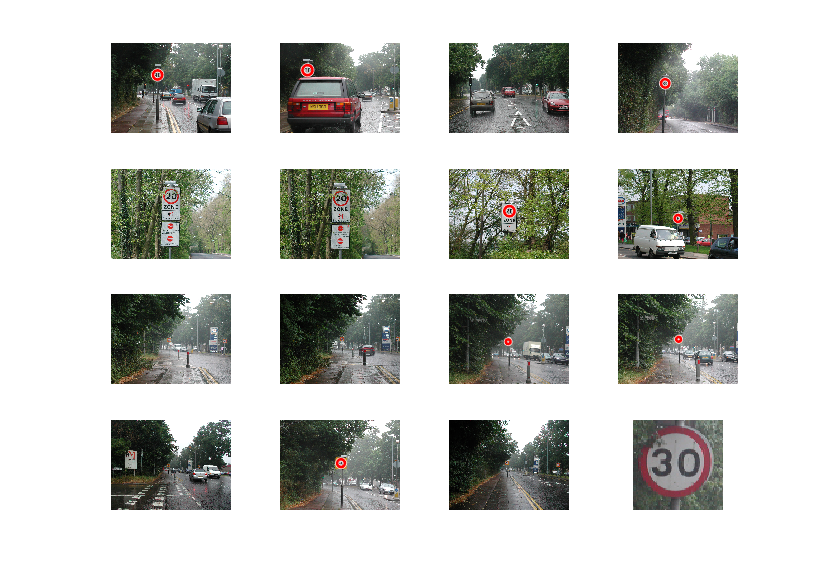

path = 'C:\Users\CS-Guest-2\Desktop\Nuig\MSc_AI\MSc-AI\Embeded_Image\stress';
imagefiles = dir(fullfile(path,'*.TIF'));
for i=1:5
    filename = fullfile(path,imagefiles(i).name);
    I = imread(filename);  
    [centers,radii] = imfindcircles(I,[9 70],'ObjectPolarity','bright', ...
    'Sensitivity',0.82);  
    if centers
         center = centers(1:1,:)
        radius = radii(1:1)
        viscircles(centers,radii);
        x = centers(1) - (1.5 * radii);
        X = 70;
        y = centers(2) - (1.5 * radii);
        Y = 70;
        img = imcrop(I,[x y X Y]);
       
        imshow(img);
        pause(1)
    end
   
end

%{
[centers,radii] = imfindcircles(I,[15 45],'ObjectPolarity','bright','Sensitivity',0.82)  
imshow(path)
h = viscircles(centers,radii);

%}